# Image-Based Defect Detection for Manufacturing Inspection

## Break Down the Problem

**In the space below, define the problem statement:**

In the manufacturing industry, human error is to be expected when it comes to determining if products pass a certain standard of high quality to be distributed. With human error, technology becomes a method to mitigate risks to detect defective products more efficiently with pattern recognition. However, as technology becomes commonly integrated in the industry, it poses problems to workers that need simpler technological functions to be able to utilize with ease. Thus, there’s a growing need for technology to become simpler and accessible for people to use.

**List the requirements, constraints, and success criteria for the project:**

The given requirements for the project would be to utilize MATLAB with additional functions as listed: Deep Learning Toolbox, Deep Learning Toolbox for ResNet-18 Network, and Image Processing Toolbox. On top of those requirements, we will be using the “Metals Parts Defect Detection” dataset to analyze metal plates. 

The presenting constraints would be that the program would only be able to detect defects in metal plates, meaning any other object besides metal plates would not be processed or recognized. With a specialized program that can only analyze metal parts, it signifies that there’s a higher threshold to find even the smallest defects that compensates for the lack of variety of products that the code can only comprehend.

The main success criteria would be if the program can give a simple “Pass” or “Fail” for each metal part the program can analyze. On top of that, an intricate, binary image that highlights each defect on a metal plate would be shown side by side with the original image as well.

**What is your proposed solution?**

With the growing advancement of AI being integrated in manufacturing inspection technology, workers in the manufacturing industries need to be able to utilize an image processing program that can detect defects on certain parts for quality control. Thus, an AI-integrated function that can instantly give results if a product passes or fails the quality standards, would be the most cost-efficient and simpler solution for the problem. 

#### Approach and Methodology

The approach for the entire program was attempt writing first, look at the documentation or ask a teammate if stuck, and if both do not work, use Google to research the issue or get aid from AI.

Generally, we prioritize discussing with teammates before using Google or AI.

#### Design Decisions and Trade-offs

A big part of the program was hard-coded, such as: the datastore, the labels/classifications, and the sizing of the figures/graphs. What this means is that this program will likely not work for any other type metal part other than blue metal plates. It will also likely not display all the data correctly if the screen is too small or too big.

## Task 1: Explore and Organize Image Dataset

### Challenges

This task was fairly straight-forward with no challenges, as it only required us to import our dataset. We covered this in the Image Processing Onramp.

% Metal Parts Defect Detection Dataset

partsBS = imageDatastore("Datasets/metal_plate/test/", IncludeSubfolders=true, LabelSource="foldernames");
partsLabelsCount = countEachLabel(partsBS);
imageCount = length(partsBS.Labels);

srcName = {'good', 'major_rust', 'scratches', 'total_rust'};
targetNames = {'Metal Plate', 'Major Rust', 'Scratches', 'Total Rust'};
map = containers.Map(srcName, targetNames);

% Folder Structure
dataFolder = "Datasets/metal_plate/test";
imds = imageDatastore(dataFolder, 'IncludeSubfolders', true, 'LabelSource', 'foldernames');

% Remaps labels if the foldernames aren't canonical
labels = cellstr(imds.Labels);
for i = 1:numel(labels)
    key = labels{i};
    if isKey(map, key)
        labels{i} = map(key);
    end
end
imds.Labels = categorical(labels);

% Saves Labels Table
T = table(imds.Files, cellstr(imds.Labels), 'VariableNames', {'File', 'Label'});
writetable(T, fullfile(dataFolder, 'labels_table.csv'));

% Check counts per class and view example images to verify labeling.
counts = countEachLabel(imds)

counts = 4×2 table
       Label       Count
    ___________    _____

    Major Rust      14  
    Metal Plate     26  
    Scratches       34  
    Total Rust      23  



%% Merge FAIL subclasses for Binary Evaluation
binaryLabels = cellstr(imds.Labels);
isFail = ismember(binaryLabels, {'Major Rust', 'Scratches'});
binaryLabels(isFail) = {'FAIL'};
binaryLabels(~isFail) = {'PASS'};

Tbinary = table(imds.Files, binaryLabels, 'VariableNames', {'File','BinaryLabel'});
writetable(Tbinary, fullfile(dataFolder,'labels_table_binary.csv'));

## Task 2: Build a Single-Image Inspection Function

### Challenges

function [numComponents, maxArea, areaRatio] = InspectImage(img)
    % Single-image Inspection Function to identify and quantify defects
    % Inputs:
    %   img           - Classifiable image, preferably RGB
    % Outputs:
    %   numComponents - Number of defects
    %   maxArea       - Max area of all defects
    %   areaRatio     - Fraction of the image flagged as suspicious

    defectMask = PreprocessImage(img);

    % Connected components analysis on defects/rust
    cc = bwconncomp(defectMask);
    numComponents = cc.NumObjects;
    
    rp = regionprops(cc, "Area");
    areas = [rp.Area];

    if isempty(areas)
        maxArea = 0;
    else
        maxArea = max(areas);
    end
    
    areaRatio = nnz(defectMask) / numel(defectMask);
end

function defectMask = PreprocessImage(image)
    if ~isa(image, 'uint8')
        image = im2uint8(image);
    end

    % =========================================================================
    % STEP 1: CLEAR CANVAS / BACKGROUND
    % =========================================================================
    hsvI = rgb2hsv(image);
    labI = rgb2lab(image);
    L = rgb2gray(image);
    sat = hsvI(:,:,2);
    val = hsvI(:,:,3);
    a = labI(:,:,2);
    b_lab = labI(:,:,3);

    fgMask = (sat > 0.08) | (val < 0.75 & sat > 0.03);
    fgMask = bwareaopen(fgMask, 350);

    % =========================================================================
    % STEP 2: CLEAR HOOK / HANGING WIRE (Robust Isolation)
    % =========================================================================
    R_chan = double(image(:,:,1));
    G_chan = double(image(:,:,2));
    
    % Target bright, color-neutral metallic wire components
    wireCandidate = (L > 85) & (sat < 0.15) & (abs(R_chan - G_chan) < 15);
    
    ccWire = bwconncomp(wireCandidate);
    statsWire = regionprops(ccWire, 'MajorAxisLength', 'MinorAxisLength', 'Area');
    hookMask = false(size(wireCandidate));
    
    for k = 1:ccWire.NumObjects
        maj = statsWire(k).MajorAxisLength;
        minr = max(statsWire(k).MinorAxisLength, 1);
        if (maj / minr > 3.0) || (statsWire(k).Area < 4000)
            hookMask(ccWire.PixelIdxList{k}) = true;
        end
    end
    
    % Dilate generously to fully cover the wire and its shadow edges
    hookMask = imdilate(hookMask, strel('disk', 6));
    
    % Strip the hook out of the canvas immediately
    cleanFg = fgMask & ~hookMask;

    % =========================================================================
    % STEP 3: FIND PLATE (Leave holes open to exclude the center mount hole)
    % =========================================================================
    plateMask0 = bwareaopen(cleanFg, 5000);
    ccp = bwconncomp(plateMask0);
    
    if ccp.NumObjects > 1
        statsP = regionprops(ccp, 'Area');
        [~, idx] = max([statsP.Area]);
        plateMask = false(size(plateMask0));
        plateMask(ccp.PixelIdxList{idx}) = true;
    else
        plateMask = plateMask0;
    end

    % =========================================================================
    % STEP 4: DETECT DEFECTS
    % =========================================================================
    I = im2double(image);
    R = I(:,:,1); G = I(:,:,2); Bc = I(:,:,3);
    isBlue = (Bc - R > 0.08) & (Bc - G > 0.05);

    % Use plateMask directly (unfilled) so the center mounting hole is excluded
    candidateDefects = plateMask & ~isBlue;
    
    bright = L > 200;
    rust = (b_lab > 10) & (a < 5);
    candidateDefects = candidateDefects | (plateMask & (bright | rust));

    % Safety filter to strip out any leftover wire pixels
    isGreyWire = (L > 85) & (sat < 0.15) & (abs(R_chan - G_chan) < 15);
    candidateDefects = candidateDefects & ~isGreyWire;

    candidateDefects = bwareaopen(candidateDefects, 250);
    se = strel('disk', 3);
    candidateDefects = imclose(candidateDefects, se);
    candidateDefects = imopen(candidateDefects, se);

    cc = bwconncomp(candidateDefects);
    stats = regionprops(cc, 'Area', 'MajorAxisLength', 'MinorAxisLength', 'Solidity');
    for i = 1:cc.NumObjects
        maj = stats(i).MajorAxisLength;
        minr = max(stats(i).MinorAxisLength, 1);
        ar = maj / minr;
        if stats(i).Area < 300 || ar > 5 || stats(i).Solidity < 0.2
            candidateDefects(cc.PixelIdxList{i}) = 0;
        end
    end

    defectMask = logical(candidateDefects);
end

## Task 3A: Train and Integrate an AI Classifier into your Single-Image Inspection Function

### Challenges

There was some difficulty in finding how to get a prediction from the network, but the documentation for getting started with transfer learning does a good job of explaining what functions to use without going too in-depth that it gets confusing.

function [aiLabel, aiScore] = AIClassify(net, imgForNet)
    % Inputs:
    %   net       - The trained neural network
    %   imgForNet - Image patch (grayscale or RGB) to classify
    % Outputs:
    %   aiLabel   - "good", "major_rust", "scratches", "total_rust"
    %   aiScores  - Scalar confidence in range 0 to 1

    % Resize the image for ResNet-18
    imgResized = imresize(imgForNet, [224 224]);
    if size(imgResized, 3) == 1
        imgResized = repmat(imgResized, [1 1 3]); % Convert image to 3 channel if grayscale (Just in case)
    end
    
    % The labels and class names
    classNames = ["good" "major_rust" "scratches" "total_rust"];

    % Get a prediction from the network
    scores = minibatchpredict(net, imgResized);
    [maxScore, maxIndex] = max(scores);
    
    aiLabel = classNames(maxIndex);
    aiScore = maxScore;
end

## Task 3B: Combine outputs into a hybrid inspection result

### Challenges

Getting good numbers to work around with the evidence based method was a bit of trial and error, as the masks sometimes catch the hook in good images, or a few off-pixels, so I tried my best to account for that, but it is not perfect by any means. 

function [finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecisions] = InspectPart(img, trainedNet)
    % Single-image inspector: Inspects a single image and classifies it as
    % PASS or FAIL based on AI and evidence metrics.
    % Inputs:
    %   img        - Classifiable image, preferably RGB
    %   trainedNet - Trained ResNet18 Network
    % Outputs:
    %   finalLabel, confidenceScore, evidenceOverlay, evidenceMetrics, baselineDecision
    
    % Evidence mask and metrics
    imgMask = PreprocessImage(img); % Get a mask of the image defects for later
    [evidenceMetrics.numComponents, evidenceMetrics.maxArea, evidenceMetrics.areaRatio] = InspectImage(img);
    
    % Baseline evidence based decision
    Amax = 4000; Nmax = 3; % How much breathing room the evidence based method has to either pass or fail an image
    if evidenceMetrics.maxArea > Amax || evidenceMetrics.numComponents > Nmax
        baselineDecisions.evidence = "FAIL";
    else
        baselineDecisions.evidence = "PASS";
    end
    
    % AI classification (compute after evidence so we can inspect both)
    [aiLabel, aiScore] = AIClassify(trainedNet, img);  % returns network class label and score
    
    finalLabel.classBased = aiLabel; % For use in the confusion matrix

    % Map AI classification to PASS/FAIL
    if aiLabel == "good"
        baselineDecisions.AI = "PASS";
    else
        baselineDecisions.AI = "FAIL";
    end
    
    % Final label logic
    if baselineDecisions.evidence == "FAIL" || baselineDecisions.AI == "FAIL"
        finalLabel.simplified = "FAIL";
    else
        finalLabel.simplified = "PASS";
    end
    
    % Return confidence score (AI score)
    confidenceScore = double(aiScore);
    
    % Simple overlay highlighting defects
    evidenceOverlay = img;
    % Checks if image is by chance grayscale (should never happen in this case)
    if ismatrix(evidenceOverlay)
        evidenceOverlay = repmat(evidenceOverlay,1,1,3);
    end
    % Separate the three color channels
    rChannel = evidenceOverlay(:,:,1);
    gChannel = evidenceOverlay(:,:,2);
    bChannel = evidenceOverlay(:,:,3);
    
    opacity = 0.3;
    translucency = 1 - opacity;

    % Applies a translucent red blend over the defect area
    rChannel(imgMask) = rChannel(imgMask) * translucency + (255 * opacity);
    gChannel(imgMask) = gChannel(imgMask) * translucency;
    bChannel(imgMask) = bChannel(imgMask) * translucency;

    % Recombine everything into the final evidence overlay
    evidenceOverlay(:,:,1) = rChannel;
    evidenceOverlay(:,:,2) = gChannel;
    evidenceOverlay(:,:,3) = bChannel;
end

## Task 4: Evaluate Inspection System Performance

### Challenges

This task in particular was very difficult for me because of my unfamiliarity with the programming language and the functions I can use. Storing all the data from the InspectPart function in particular was difficult because I did not know of the intricacies of cells. You are able to store and access data with either () or {}, and not knowing this distinction led to some frustrating bugs in the process of testing the program. Almost equally frustrating for me for a little bit was the fact that the confusion matrix was using the underscore(_) in the image labels to format the text shown, leading to subscript letters, so I had to look up how I could possibly fix that small issue. Past that, displaying a table in an .mlx file is somewhat difficult, and so I simply excluded ; which has led to the program not displaying the table at all sometimes, but it is somewhat uncommon, and I much prefer the format used by MATLAB as opposed to any other sort of format I could do with the disp() function.

Displaying the final montage of all images was the most difficult part of this function. Because of the limited space on the screen, the images shown were too small when MATLAB auto resized them. This led to me trying tiled layouts, which fixed the issue temporarily. Unfortunately, after adding the data in text the resizing issue continued, leading me to come up with the current solution which takes a large amount of space in the .mlx and .pdf files, but is a good compromise for making the images somewhat easier to see.

function RunInspectionSuite(imgDS)
    % Splits the given datastore into training, validation, and testing
    [imgDSTrain, imgDSValidation, imgDSTest] = splitEachLabel(imgDS,0.6,0.15,0.25,"randomized");

    % Loading the recommended pretrained network 
    net = imagePretrainedNetwork("resnet18", NumClasses=4);
    
    % Since resnet can only use 224x224 images, resize the data stores using augmentedImageData
    augTrain = augmentedImageDatastore([224 224 3], imgDSTrain);
    augValidation = augmentedImageDatastore([224 224 3], imgDSValidation);
    
    % Sets the training options for the pretrained network
    options = trainingOptions("adam", ...
        ValidationData=augValidation, ...
        InitialLearnRate=1e-4, ... 
        ValidationFrequency=2, ...
        Plots="training-progress", ... 
        MaxEpochs=30, ...
        Metrics="accuracy", ...
        Verbose=false);
    
    % Fine tune the network for this case
    trainedNet = trainnet(augTrain, net, "crossentropy", options); % This is the main network that will be used
    
    % Some basic metrics on the test datastore
    numTestImages = length(imgDSTest.Files);
    actualLabels = imgDSTest.Labels;
    predictedLabels = strings(numTestImages, 1);

    % All the outputs for each image (Both AI and Evidence data stored here)
    finalLabels = cell(numTestImages); % .classBased or .simplified
    confidenceScores = zeros(numTestImages);
    evidenceOverlays = cell(numTestImages);
    evidenceMetrics = cell(numTestImages); % .numComponents, .maxArea, or .areaRatio
    baselineDecisions = cell(numTestImages); % .evidence or .AI

    %% Get predictions from all test images
    for i = 1 : numTestImages
        img = readimage(imgDSTest, i);
        [finalLabels{i}, confidenceScores(i), ...
            evidenceOverlays{i}, evidenceMetrics{i}, ...
            baselineDecisions{i}] = InspectPart(img, trainedNet);
        predictedLabels(i) = finalLabels{i}.classBased;
    end

    % Clean current labels to get rid of _, as it messed with confusion matrix formatting
    currentCats = categories(actualLabels);
    cleanCats = strrep(currentCats, '_', ' ');

    % Convert to categorical arrays for the confusion matrix ALSO rename
    % for clean showing
    predictedLabelsCat = categorical(predictedLabels, categories(actualLabels));
    actualLabels = renamecats(actualLabels, cleanCats);
    predictedLabelsCat = renamecats(predictedLabelsCat, cleanCats);

    %% Generate a confusion matrix
    figure;
    confusionchart(actualLabels, predictedLabelsCat, ...
        "Title", "System Performance: Actual vs. Predicted", ...
        "RowSummary", "row-normalized", ...
        "ColumnSummary","column-normalized");

    isPassActual = (actualLabels == "good");
    isPassPredicted = (predictedLabelsCat == "good");

    % Calculate the yields based on the true labels (actualLabels) and
    % those predicted by the AI (predictedLabelsCat)
    totalParts = numTestImages;
    actualYield = sum(isPassActual) / totalParts * 100;
    predictedYield = sum(isPassPredicted) / totalParts * 100;

    %% Display the yield in a bar chart
    figure;
    yieldBarChart = bar([actualYield, predictedYield]);
    yieldBarChart.FaceColor = "flat";
    yieldBarChart.CData(1,:) = [0.1 0.3 0.6];
    yieldBarChart.CData(2,:) = [0.7 0.4 0.1];

    ylim([0 100]);
    ylabel("Yield (%)");
    title("Manufacturing Yield: Actual vs. Predicted");
    xticklabels({"Actual Yield", "Predicted Yield"});

    % Display the actual percentages
    text(1, actualYield + 5, sprintf("%.1f%%", actualYield), "HorizontalAlignment", "center", "FontSize", 12);
    text(2, predictedYield + 5, sprintf("%.1f%%", predictedYield), "HorizontalAlignment", "center", "FontSize", 12);
    
    %% Summarize counts of predicted defects
    predictedDefects = predictedLabelsCat(predictedLabelsCat ~= "good");
    predictedDefectCounts = countcats(predictedDefects);
    defectTypes = categories(predictedDefects);

    % Summarize counts of ACTUAL defects
    actualDefects = actualLabels(actualLabels ~= "good");
    actualDefectCounts = countcats(actualDefects);
    
    % Removes the good from the table
    predictedDefectCounts(1) = [];
    defectTypes(1) = [];
    actualDefectCounts(1) = [];

    % Displays the defect counts
    defectTable = table(defectTypes(:), predictedDefectCounts(:), actualDefectCounts(:), ...
        VariableNames=["Defect Type", "Predicted Count", "Actual Count"])
    
    %% Display a montage of common failure cases
    misclassifiedIdx = find(actualLabels ~= predictedLabelsCat);

    if ~isempty(misclassifiedIdx)
        numErrors = length(misclassifiedIdx);
        
        figure; % Went with a tiled layout because it seemed easier to add a title to the pictures
        t = tiledlayout("flow", "TileSpacing","compact", "Padding","none");
        title(t, sprintf("Common Failure Cases: %d Misclassifications", numErrors));

        for i = 1 : numErrors
            idx = misclassifiedIdx(i);
            img = readimage(imgDSTest, idx);

            nexttile;
            imshow(img);
            titleStr = sprintf("True: %s\nPred: %s", string(actualLabels(idx)), string(predictedLabelsCat(idx)));
            title(titleStr, "Color", "red", "FontSize", 9, "Interpreter", "none");
        end

    else
        disp("No misclassifications found in the test set.");
    end

    %% To show the rest of the data we gathered
    imagesPerFigure = 2;
    for i = 1 : numTestImages
        if mod(i-1, imagesPerFigure) == 0
            figure;

            t = tiledlayout(1, 2, "TileSpacing", "loose", "Padding", "normal");
            title(t, "Evidence Metrics and PASS/FAIL Scores");
        end
        nexttile;
        img = readimage(imgDSTest, i);
        mask = PreprocessImage(img);
        % Montage of the image unedited, it's evidence overlay, and the
        % mask of the overlay
        montage({img, evidenceOverlays{i}, mask}, "Size",[1 3]);
        headerLine = "Original | Overlay | Mask";
        % Create a multi-line string for metrics
        metricsLine = sprintf('Num Components: %d\nMax Area: %.2f\nArea Ratio: %.3f\n', ...
                              evidenceMetrics{i}.numComponents, ...
                              evidenceMetrics{i}.maxArea, ...
                              evidenceMetrics{i}.areaRatio);
        % Multi-line string for decisions
        decisionsLine = sprintf('AI: %s\n Evidence: %s\n Final: %s', ...
            baselineDecisions{i}.AI, ...
            baselineDecisions{i}.evidence, ...
            finalLabels{i}.simplified);
                              
        % Attach it directly above the montage
        title({headerLine, metricsLine, decisionsLine}, 'FontName', 'Courier', 'FontSize', 8);

    end

end


# Evaluation the Dataset with No Modifications

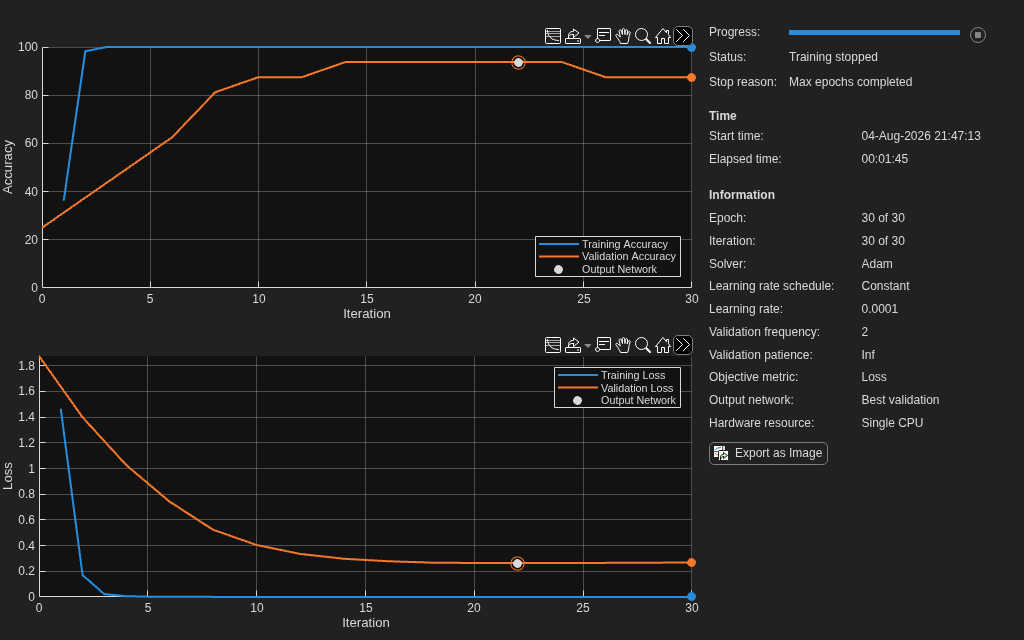

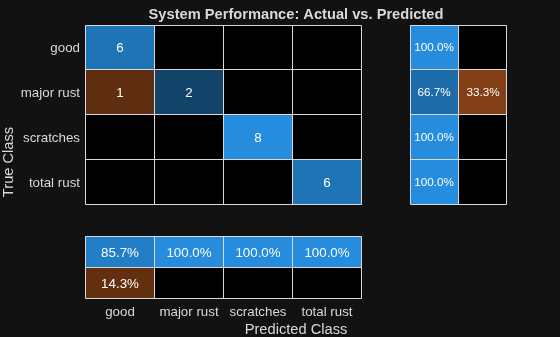

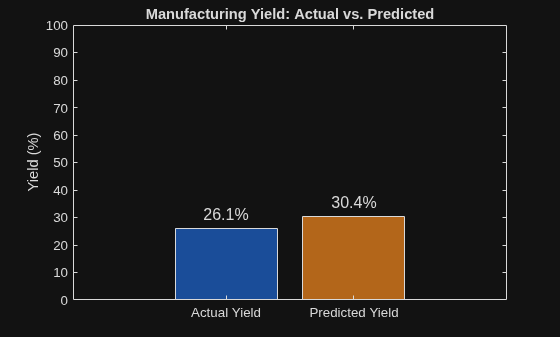

defectTable = 3×3 table
     Defect Type      Predicted Count    Actual Count
    ______________    _______________    ____________

    {'major rust'}           2                3      
    {'scratches' }           8                8      
    {'total rust'}           6                6      


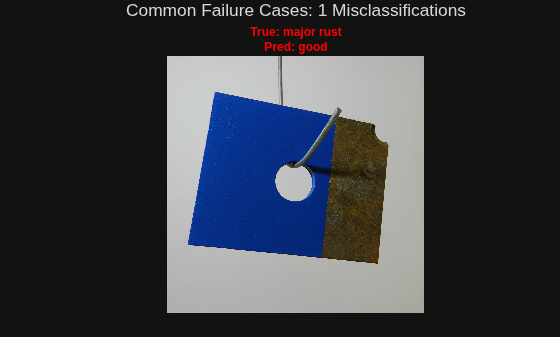

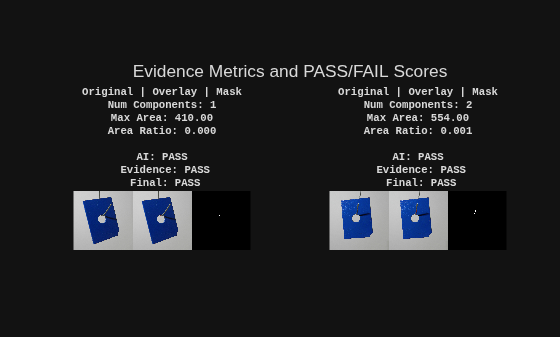

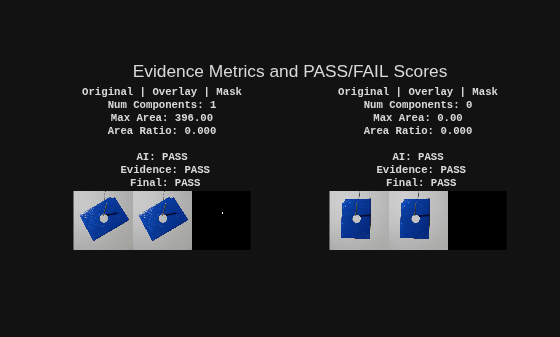

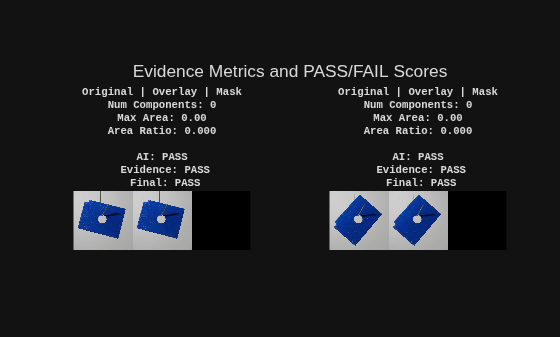

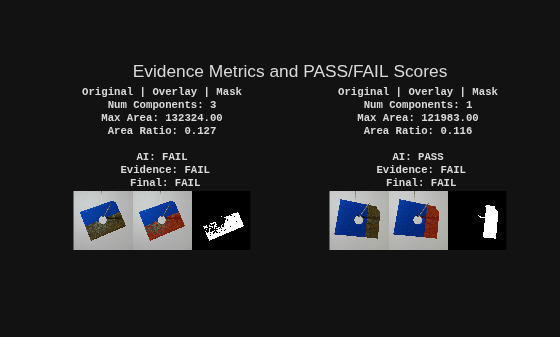

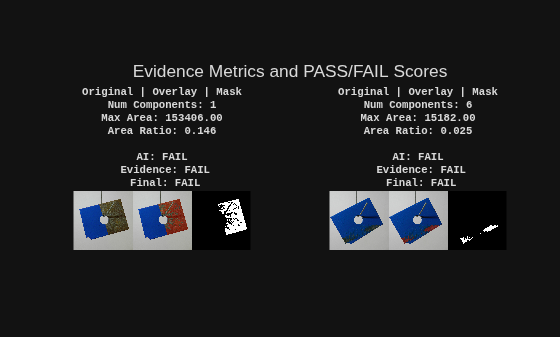

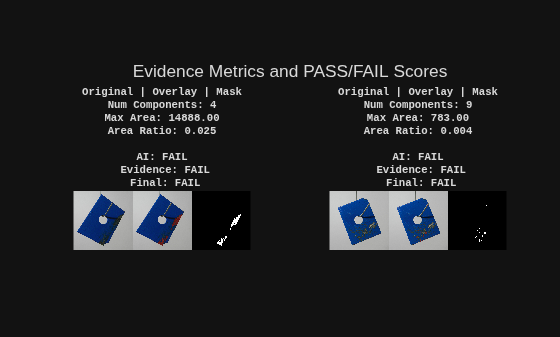

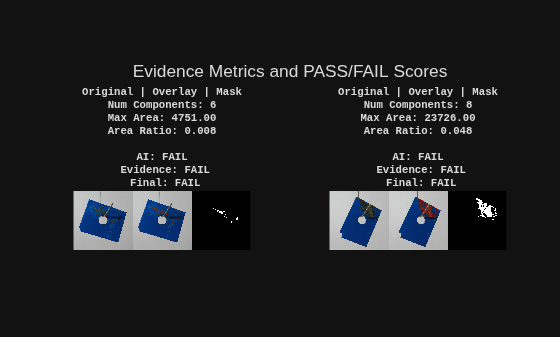


RunInspectionSuite(partsBS);

## Task 5: Test and Evaluate System Robustness  

### Challenges

srcDS = imageDatastore("Datasets/metal_plate/test", "IncludeSubfolders", true, "LabelSource","foldernames");
baseOutDir = "Datasets/metal_plate";

distortions = ["contrast", "blur", "noise"];

% Apply distortions to the images in the datastore
for d = 1:length(distortions)
    distType = distortions(d);
    destDir = fullfile(baseOutDir, "test_" + distType);

    fprintf('Generating %s dataset in %s...\n', distType, destDir);

    % Loop through every image from original datastore
    for i = 1:numel(srcDS.Files)
        img = readimage(srcDS, i);
        [~, name, ext] = fileparts(srcDS.Files{i});
        label = string(srcDS.Labels(i));

        % Create the destination directory if it doesn't exist
        outFolder = fullfile(destDir, label);
        if ~exist(outFolder, 'dir')
            mkdir(outFolder);
        end
        
        % Apply distortion based on the current type
        switch distType
            case "contrast"
                distortedImg = imadjust(img, [0.2 0.8], []);
            case "blur"
                distortedImg = imgaussfilt(img, 2);
            case "noise"
                distortedImg = imnoise(img, 'gaussian', 0, 0.005);
        end

        % Save the distorted image to the destination directory
        imwrite(distortedImg, fullfile(outFolder, sprintf('%s_distorted%s', name, ext)));
    end
end

Generating contrast dataset in Datasets/metal_plate/test_contrast...
Generating blur dataset in Datasets/metal_plate/test_blur...
Generating noise dataset in Datasets/metal_plate/test_noise...


# Evaluating Robustness with Blur

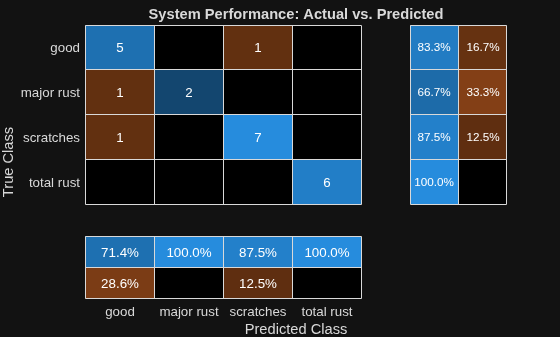

defectTable = 3×3 table
     Defect Type      Predicted Count    Actual Count
    ______________    _______________    ____________

    {'major rust'}           2                3      
    {'scratches' }           8                8      
    {'total rust'}           6                6      


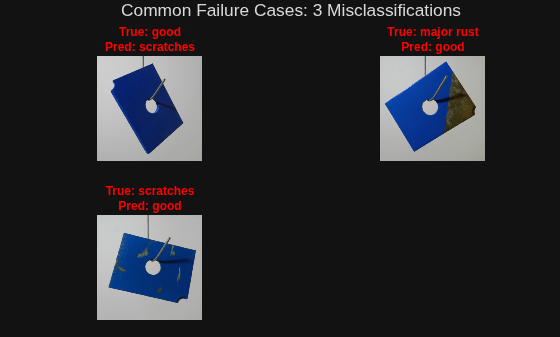

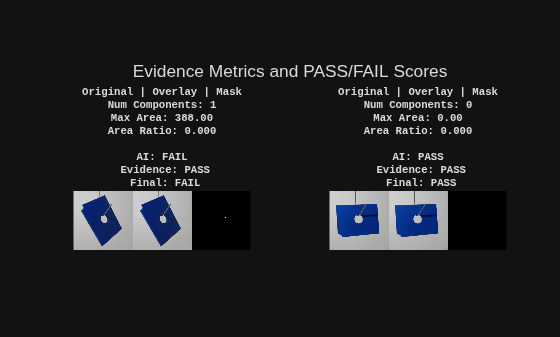

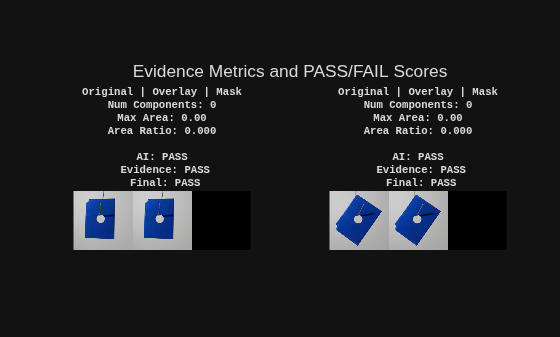

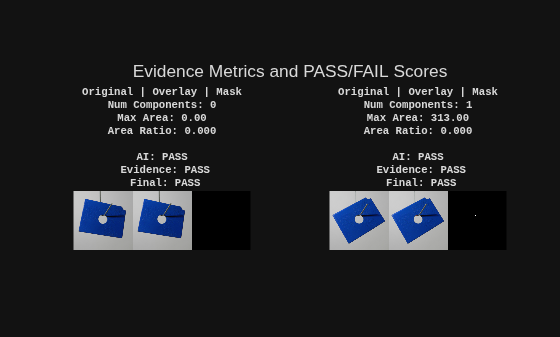

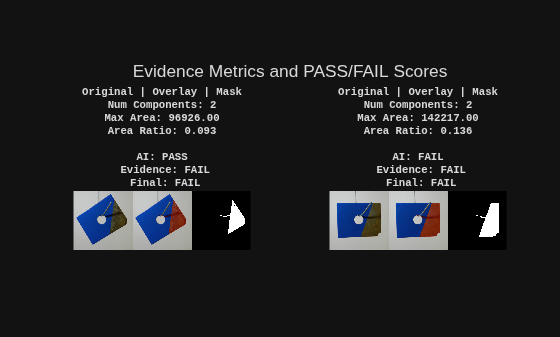

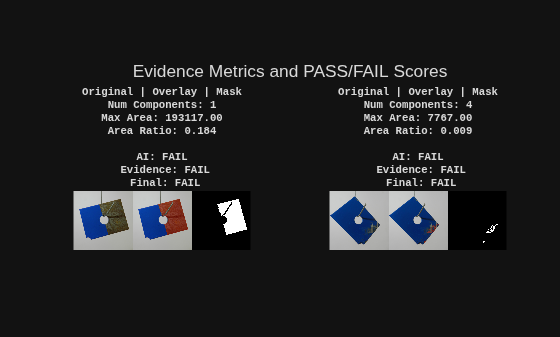

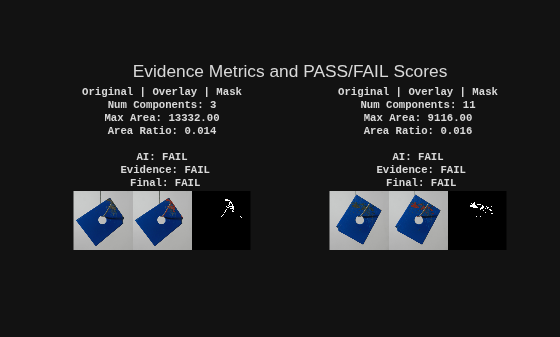

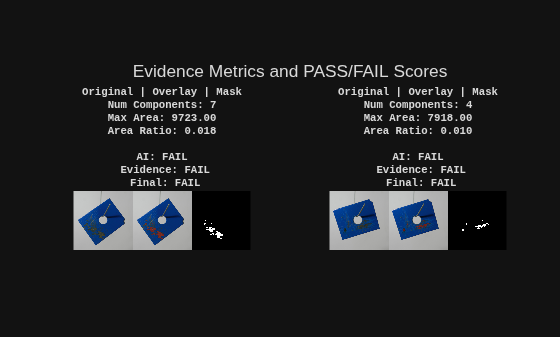

RunInspectionSuite(imageDatastore(fullfile(baseOutDir, "test_blur"), 'IncludeSubfolders', true, 'LabelSource', 'foldernames'));

# Evaluating Robustness with Noise

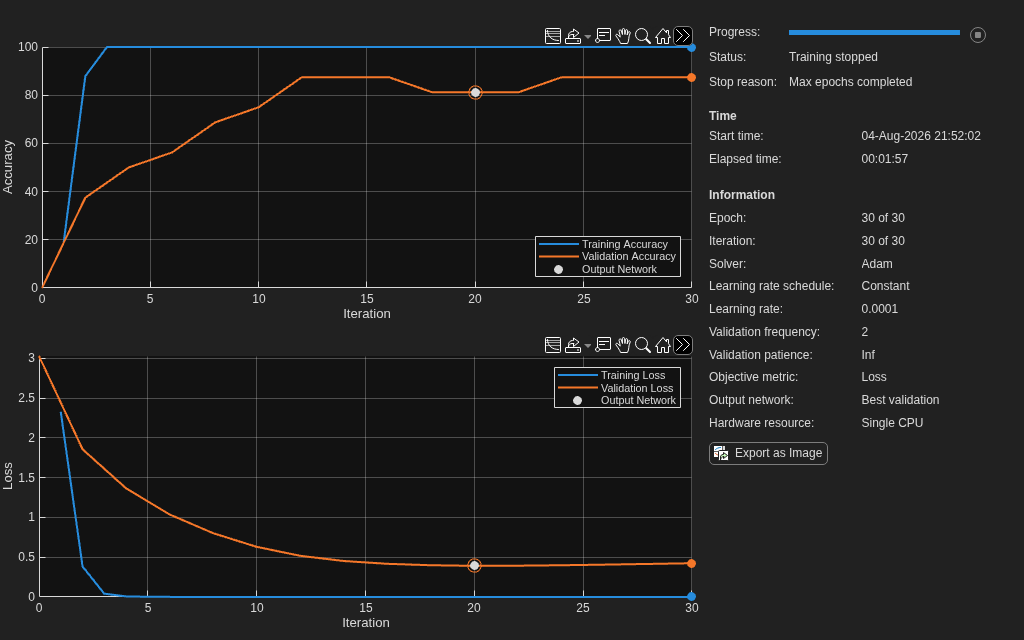

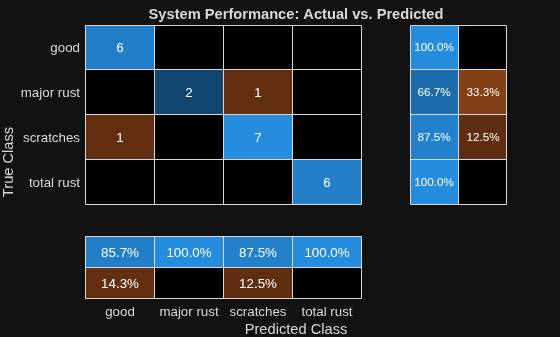

defectTable = 3×3 table
     Defect Type      Predicted Count    Actual Count
    ______________    _______________    ____________

    {'major rust'}           2                3      
    {'scratches' }           8                8      
    {'total rust'}           6                6      


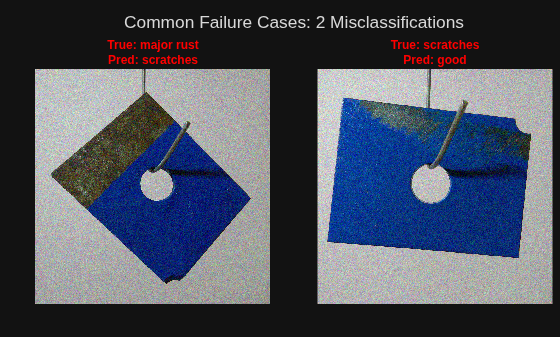

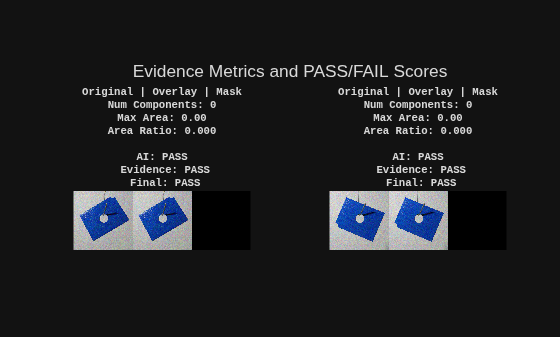

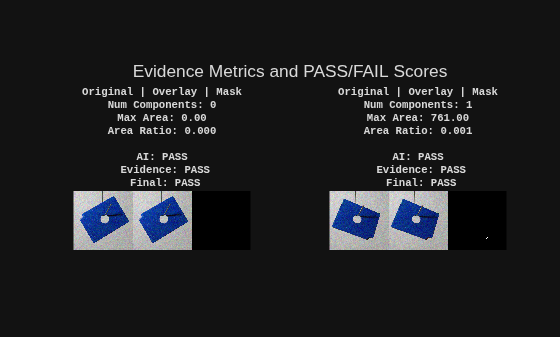

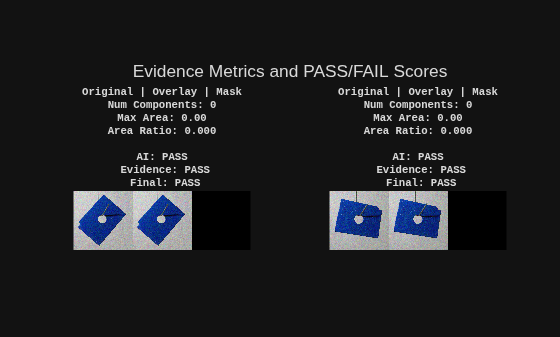

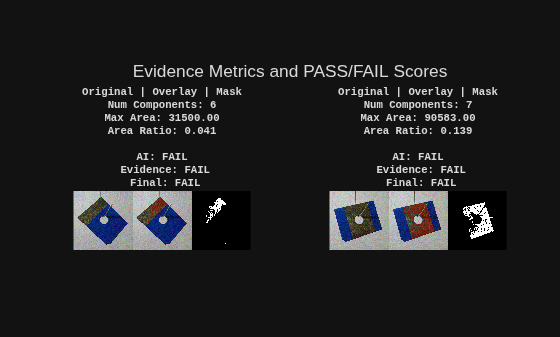

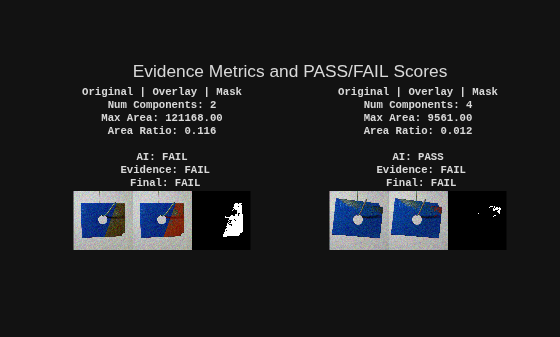

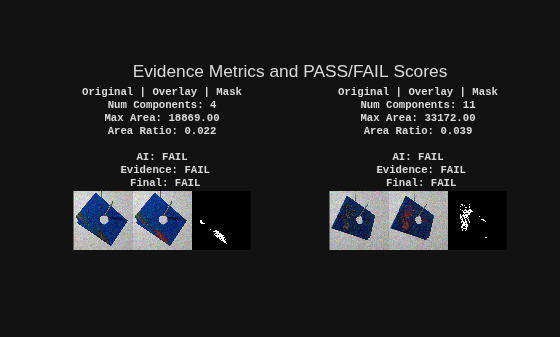

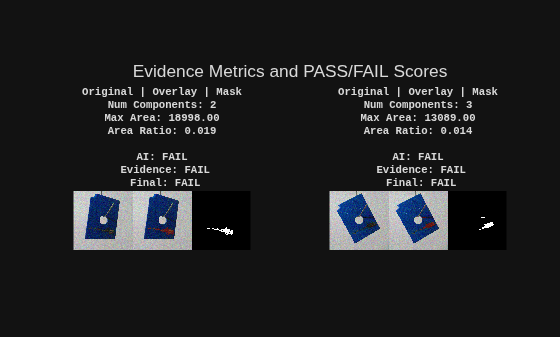

RunInspectionSuite(imageDatastore(fullfile(baseOutDir, "test_noise"), 'IncludeSubfolders', true, 'LabelSource', 'foldernames'));

# Evaluating Robustness with Contrast

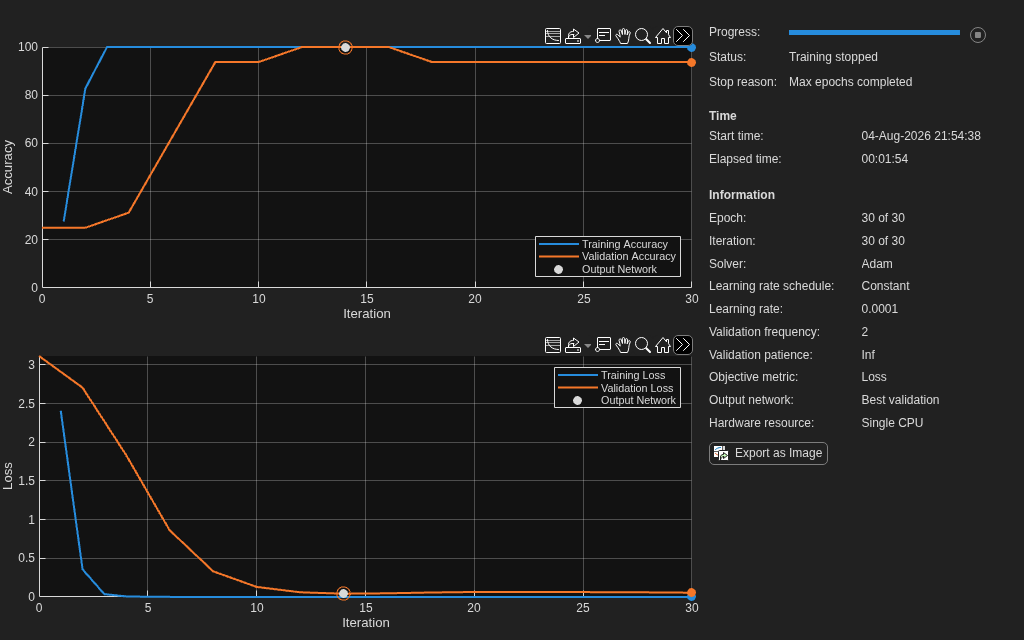

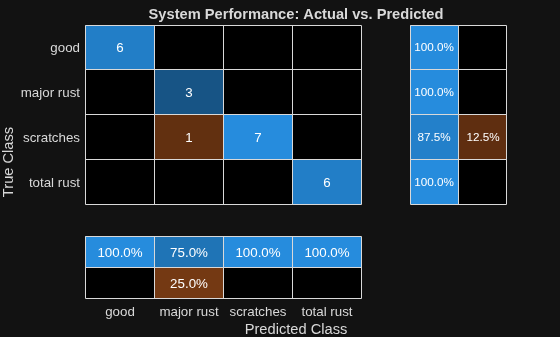

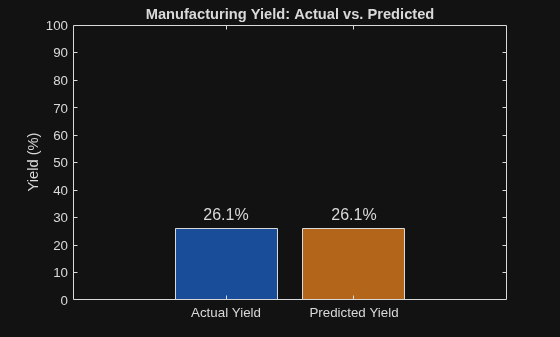

defectTable = 3×3 table
     Defect Type      Predicted Count    Actual Count
    ______________    _______________    ____________

    {'major rust'}           4                3      
    {'scratches' }           7                8      
    {'total rust'}           6                6      


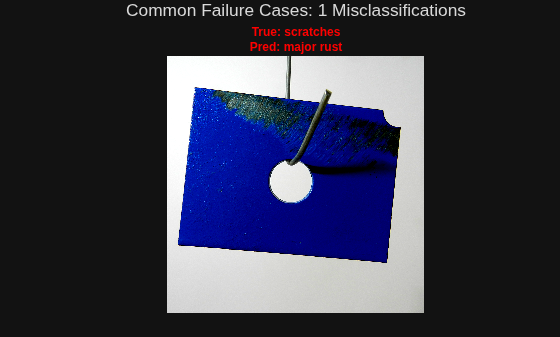

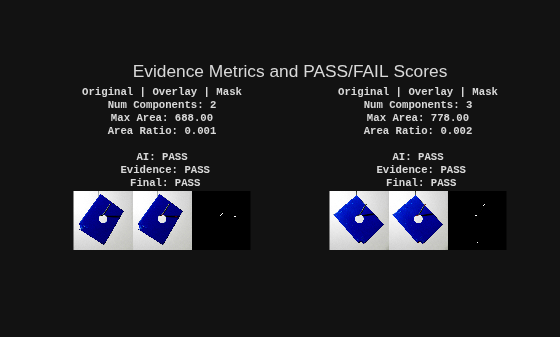

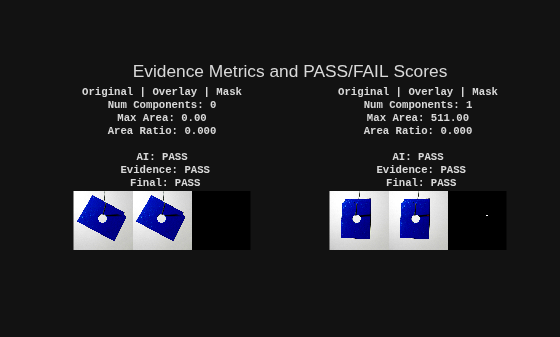

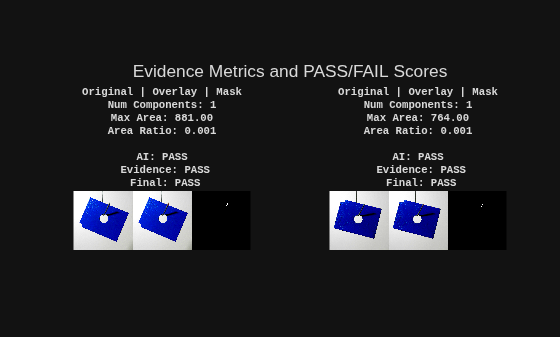

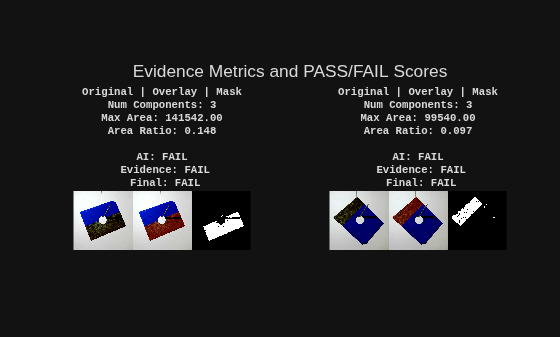

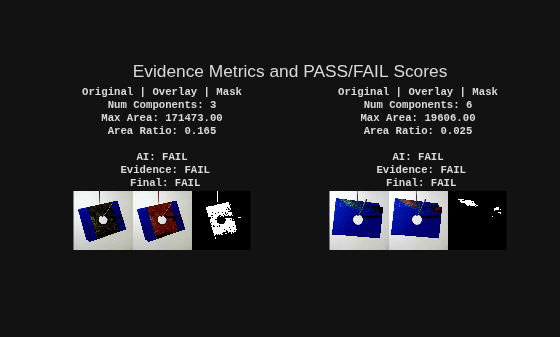

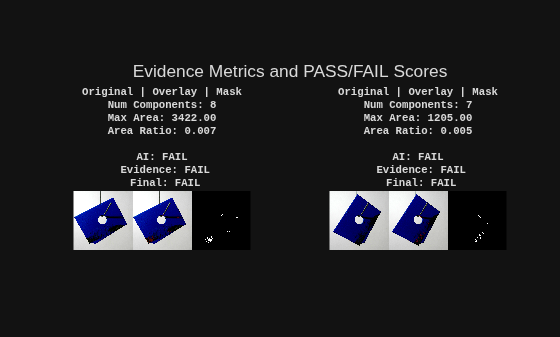

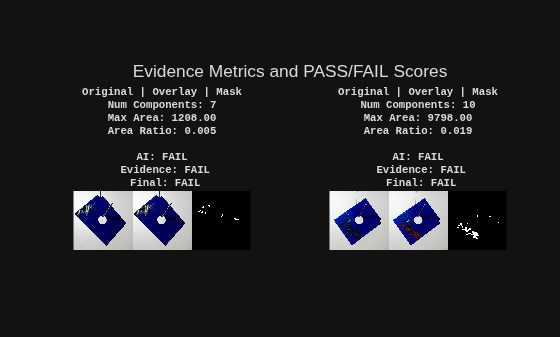

RunInspectionSuite(imageDatastore(fullfile(baseOutDir, "test_contrast"), 'IncludeSubfolders', true, 'LabelSource', 'foldernames'));

## Interpretation of Results

**Summarize your findings by interpreting their physical/engineering meaning:**

When the program runs, three images are shown to show the preprocessing stage to the final processing stage. 

The original image is shown on the left side, the middle image adds a red overlay of any defects to the original, and the right image is displayed as a binary image that is only shown in black and white. With the white primarily showing the rust, while the black means that the rest of the product is in good condition.

The results for defects are categorized as major rust, scratches, and total rust.

Major rust means that some of the original blue color remains, but a large part of the plate is filled with rust. Scratches mean there’s some minor defects that remove some of the original color. Finally, total rust means that the entire metal plate is all rust without the original blue color remaining.

Based on the displayed results from the program, the program determines that there are 3 metal plates with major rust, 8 with scratches, and finally 6 with total rust out of a small sample of 23 images from the original database that contained 97 plates. 

**What are some limitations of your work?**

Some limitations of the work would be that the team does not possess advanced knowledge in using MATLAB. However, most of the team has transferable programming skills that made the learning process of MATLAB much easier. In consideration of these limitations, the proposed solution is only able to detect defects in one category of products, metal plates, in particular. 

Technological limitations for the project would be that the AI might not process the images correctly, passing plates that might have scratches or rust. Since the analysis of the AI relies on the program’s capability to apply contrast, reduce noise, etc., there’s a higher threshold for the AI to fail due to the fact the quality of the image matters before it can go through a “Pass” or “Fail”.

When going through the preprocessing of the images, the program is heavily reliant on the plates being similar color or for those plates to be within a certain range of HSV values.The program would most likely need to be rewritten for objects with different transparency as well. A different colored background would also likely affect the final decision.

In our specific case, the dataset is small, as we only have 97 images to work with. Those 97 images are also split into 4 different categories, so what we can use for training, validation, and testing is very small. The program would likely be much more accurate with a greater variety of images, or using a different method to train the AI.

**What are practical next steps?**

Some practical next steps for the project would be to add more data to the program, so that the basis of the program can analyze more than metal plates. In the case that the project gains more manpower and expertise that can expand the capacity of the program to contain more databases.

Apart from increasing the capabilities of the program, we would also need to make it faster, as right now it trains a new AI for every run-through of the data, making it incredibly slow without a fast computer.

The program also fails to include any easy ways to import new datasets that can be quickly tested without having to rewrite the code. A good practical next step would be making this program into an application that displays any outputs in an easier to read format, while also being capable of importing new data with less of a hassle. Along with that, creating an API for automation in a factory would be ideal.